# Build Basic Rigid Body Tree Models

This example shows how to use the elements of the rigid body tree robot model to build a basic robot arm with five degrees of freedom. The model built in this example represents a common table top robot arms built with servos and an integrated circuit board.

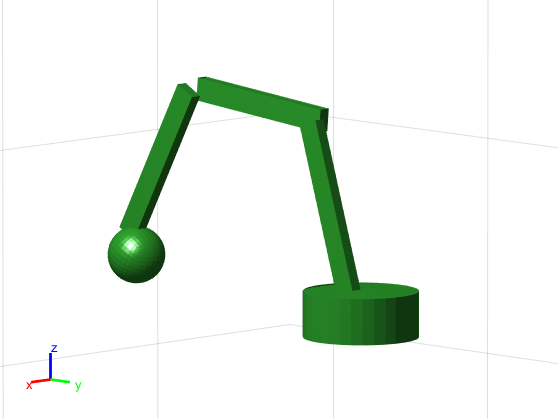

To load a robot model from a set of common commercially available robots, use the `loadrobot` function. For an example, see **Load Predefined Robot Models**.

If you have a URDF file or Simscape Multibody™ model of your robot, you can import as a rigid body tree using `importrobot`. For an example, see **Import Simscape Multibody Models.**

## Create Rigid Body Elements

First, create a `rigidBodyTree` robot model. The rigid body tree robot model represents the entire robot, which is made up of rigid bodies and joints that attach them together. The base of the robot is a fixed frame that defines the world coordinates. Adding your first body, attaches the body to the base.

robot = rigidBodyTree("DataFormat","column");
base = robot.Base;

Then, create a series of linkages as `rigidBody` objects. The robot consists of a rotating base, 3 rectangular arms, and a gripper. 

rotatingBase = rigidBody("rotating_base");
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");
gripper = rigidBody("gripper");

Create collision objects for each rigid body with different shapes and dimensions. When you create the collision objects, the coordinate frame is centered in the middle of the object by default. Set the `Pose` property to move the frame to the bottom of each body along the *z*-axis. Model the gripper as a sphere for simplicity.

collBase = collisionCylinder(0.05,0.04); % cylinder: radius,length
collBase.Pose = trvec2tform([0 0 0.04/2]);
coll1 = collisionBox(0.01,0.02,0.15); % box: length, width, height (x,y,z)
coll1.Pose = trvec2tform([0 0 0.15/2]);
coll2 = collisionBox(0.01,0.02,0.15); % box: length, width, height (x,y,z)
coll2.Pose = trvec2tform([0 0 0.15/2]);
coll3 = collisionBox(0.01,0.02,0.15); % box: length, width, height (x,y,z)
coll3.Pose = trvec2tform([0 0 0.15/2]);
collGripper = collisionSphere(0.025); % sphere: radius
collGripper.Pose = trvec2tform([0 -0.015 0.025/2]);

Add the collision bodies to the rigid body objects.

addCollision(rotatingBase,collBase)
addCollision(arm1,coll1)
addCollision(arm2,coll2)
addCollision(arm3,coll3)
addCollision(gripper,collGripper)

## Attach Joints

Each rigid body is attached using a revolute joint. Create the `rigidBodyJoint` objects for each body. Specify the *x*-axis as the axis of rotation for the rectangular arm joints. Specify the *y*-axis for the gripper. The default axis is the *z*-axis. 

jntBase = rigidBodyJoint("base_joint","revolute");
jnt1 = rigidBodyJoint("jnt1","revolute");
jnt2 = rigidBodyJoint("jnt2","revolute");
jnt3 = rigidBodyJoint("jnt3","revolute");
jntGripper = rigidBodyJoint("gripper_joint","revolute");

jnt1.JointAxis = [1 0 0]; % x-axis
jnt2.JointAxis = [1 0 0];
jnt3.JointAxis = [1 0 0];
jntGripper.JointAxis = [0 1 0] % y-axis

jntGripper =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'gripper_joint'
                 JointAxis: [0 1 0]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


Set transformations of the joint attachment between bodies. Each transformation is based on the dimensions of the previous rigid body length (*z*-axis). Offset the arm joints in the *x*-axis to avoid collisions during rotation.

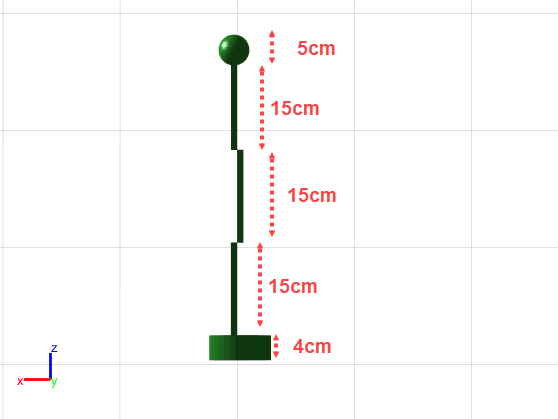

setFixedTransform(jnt1,trvec2tform([0.015 0 0.04]))
setFixedTransform(jnt2,trvec2tform([-0.015 0 0.15]))
setFixedTransform(jnt3,trvec2tform([0.015 0 0.15]))
setFixedTransform(jntGripper,trvec2tform([0 0 0.15]))

## Assemble Robot

Create an object array for both the bodies and joints, including the original base. Add each joint to the body, and then add the body to the tree. Visualize each step.

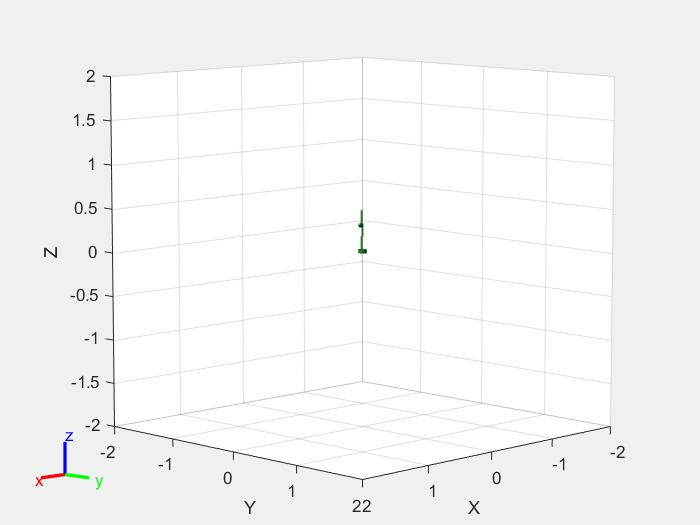

bodies = {base,rotatingBase,arm1,arm2,arm3,gripper};
joints = {[],jntBase,jnt1,jnt2,jnt3,jntGripper};

figure("Name","Assemble Robot","Visible","on")
for i = 2:length(bodies) % Skip base. Iterate through adding bodies and joints.
            bodies{i}.Joint = joints{i};
            addBody(robot,bodies{i},bodies{i-1}.Name)
            show(robot,"Collisions","on","Frames","off");
            drawnow;
end

Call the `showdetails` function to view a list of the final tree information. Ensure the parent-child relationship and joint types are correct.

showdetails(robot)

--------------------
Robot: (5 bodies)

 Idx            Body Name           Joint Name           Joint Type            Parent Name(Idx)   Children Name(s)
 ---            ---------           ----------           ----------            ----------------   ----------------
   1        rotating_base           base_joint             revolute                     base(0)   arm1(2)  
   2                 arm1                 jnt1             revolute            rotating_base(1)   arm2(3)  
   3                 arm2                 jnt2             revolute                     arm1(2)   arm3(4)  
   4                 arm3                 jnt3             revolute                     arm2(3)   gripper(5)  
   5              gripper        gripper_joint             revolute                     arm3(4)   
--------------------


## Interact With Robot Model

Visualize the robot model to confirm the dimensions using the `interactiveRigidBodyTree` object. Use the interactive GUI to move the model around. You may select specific bodies and set their joint position. To interact with more detailed models provided with Robotics System Toolbox™, see **Load Predefined Robot Models** or the `loadrobot` function.

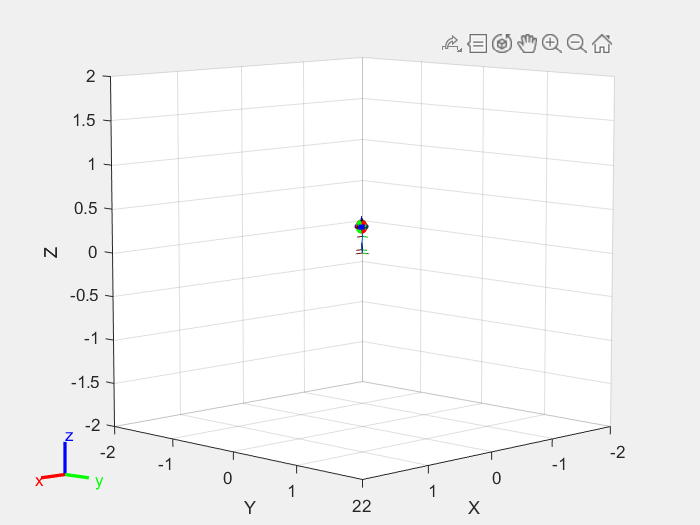

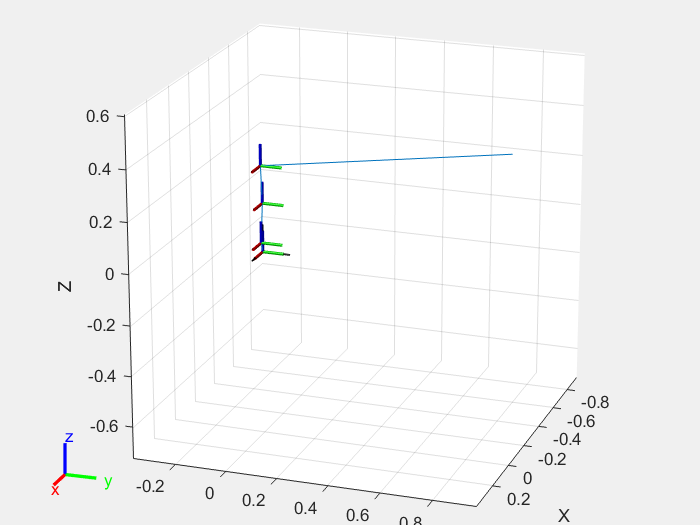

figure("Name","Interactive GUI")
gui = interactiveRigidBodyTree(robot,"MarkerScaleFactor",0.25);

Move the interactive marker around to test different desired gripper positions. The GUI uses inverse kinematics to generate the best joint configuration. For more information about the interactive GUI, see `interactiveRigidBodyTree` object.

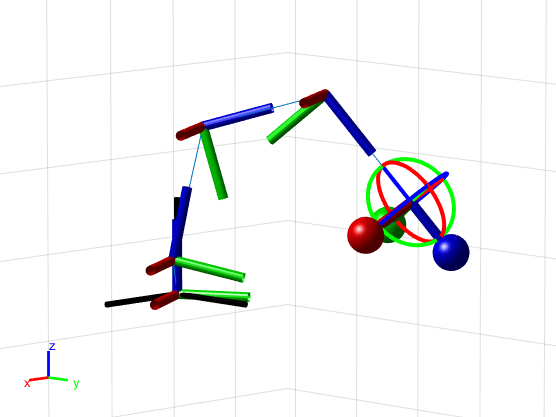

## Next Steps

Now that you built your model in MATLAB®, you may want to do many different things.

- Perform [inverse kinematics](docid:robotics_doccenter#mw_533ce698-c4bd-430c-8cb9-add59bd96640) to get joint configurations based on desired end-effector positions. Specify additional robot constraints other than the model parameters including aiming constraints, Cartesian bounds, or pose targets.

- Generate [trajectories](docid:robotics_doccenter#mw_d5333cca-a634-4d69-9ff5-1e99b99ab0e4) based on waypoints and other parameters with trapezoidal velocity profiles, B-splines, or polynomial trajectories.

- Peform [motion planning](docid:robotics_doccenter#mw_87184aa9-6b29-46a6-a396-aab126d8274f) utilizing your robot models and an rapidly-exploring random tree (RRT) path planner.

- Check for [collisions](docid:robotics_doccenter#mw_d93555e3-d6a3-4974-9088-680f8c5845f3) with obstacles in your environment to ensure safe and effective motion of your robot.

*Copyright 2022 The MathWorks, Inc.*